# Relationship Between CT and Age

## Load Data

clear;
close all;
load('dataCleaned.mat');

## Linear Fit - Age vs. CT Data

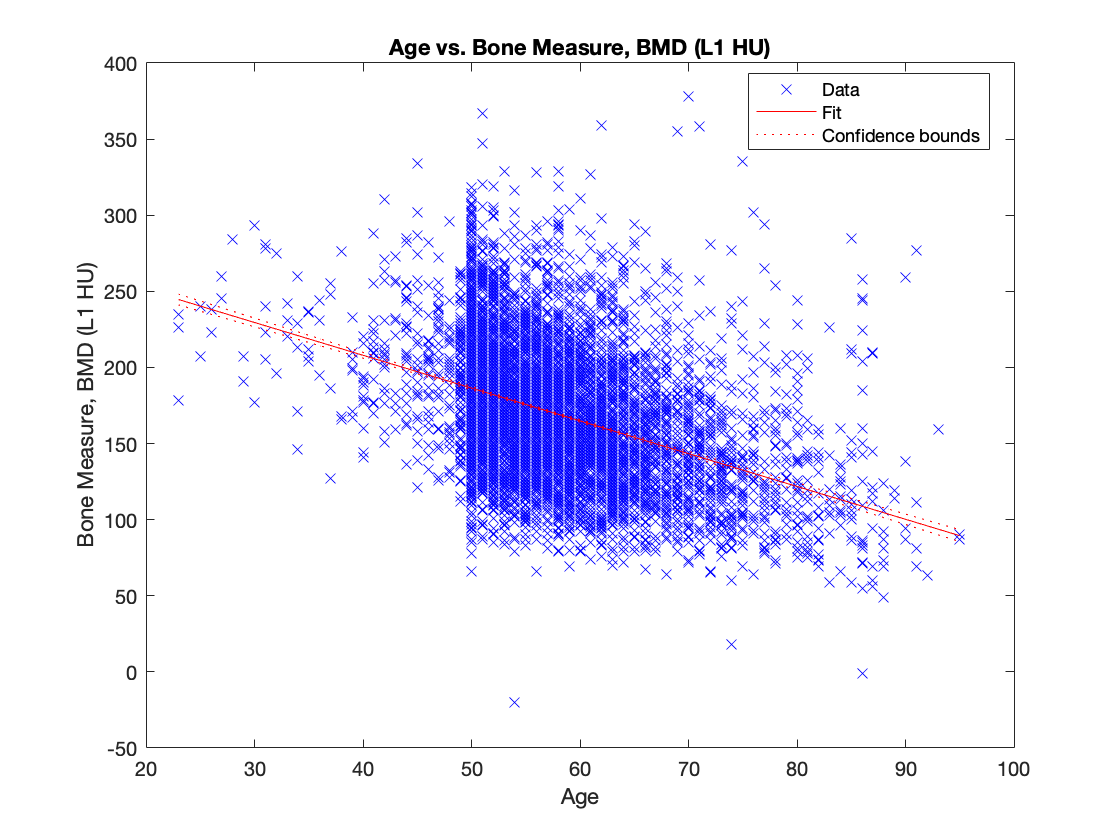

                   Estimate       SE        tStat     pValue
                   ________    ________    _______    ______
    (Intercept)     294.18       2.9779     98.788      0   
    x1             -2.1548     0.051679    -41.696      0   


The variable Bone Measure, BMD (L1 HU) is linearly related to age with p-value of 0.000000.

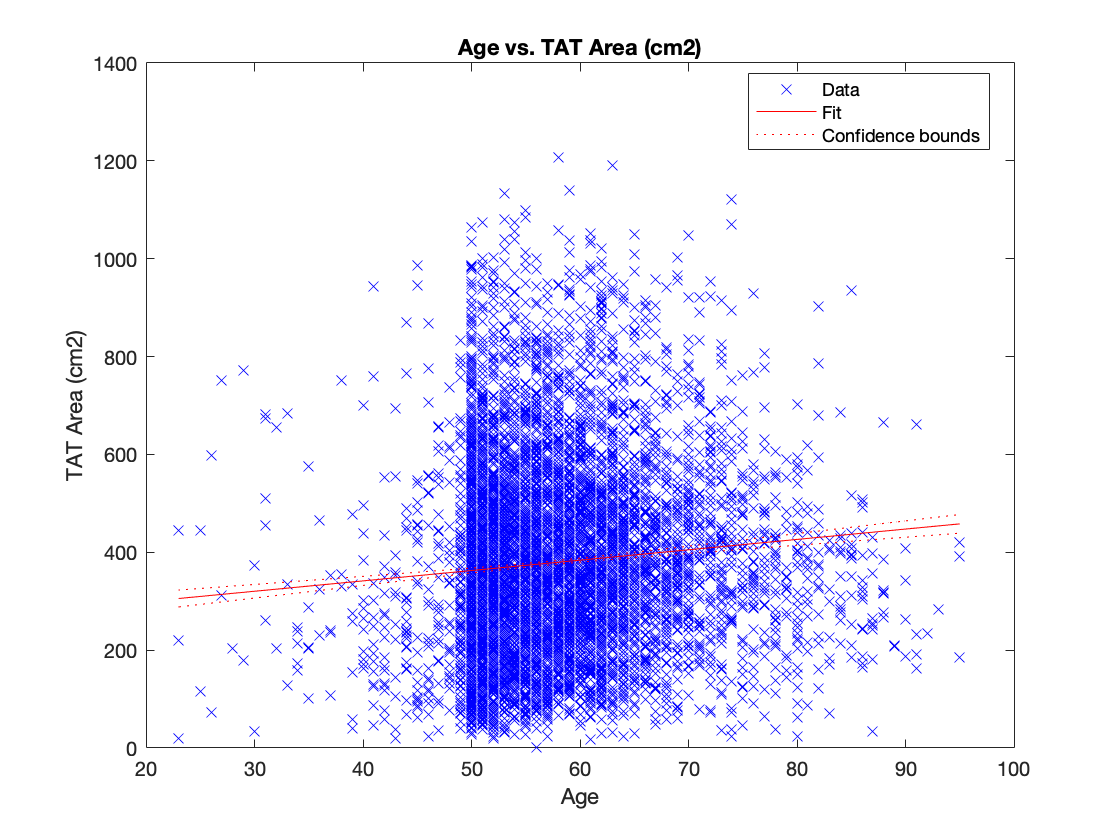

                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________
    (Intercept)     256.79      14.514    17.692    6.8273e-69
    x1              2.1187     0.25196    8.4087    4.7733e-17


The variable TAT Area (cm2) is linearly related to age with p-value of 0.000000.

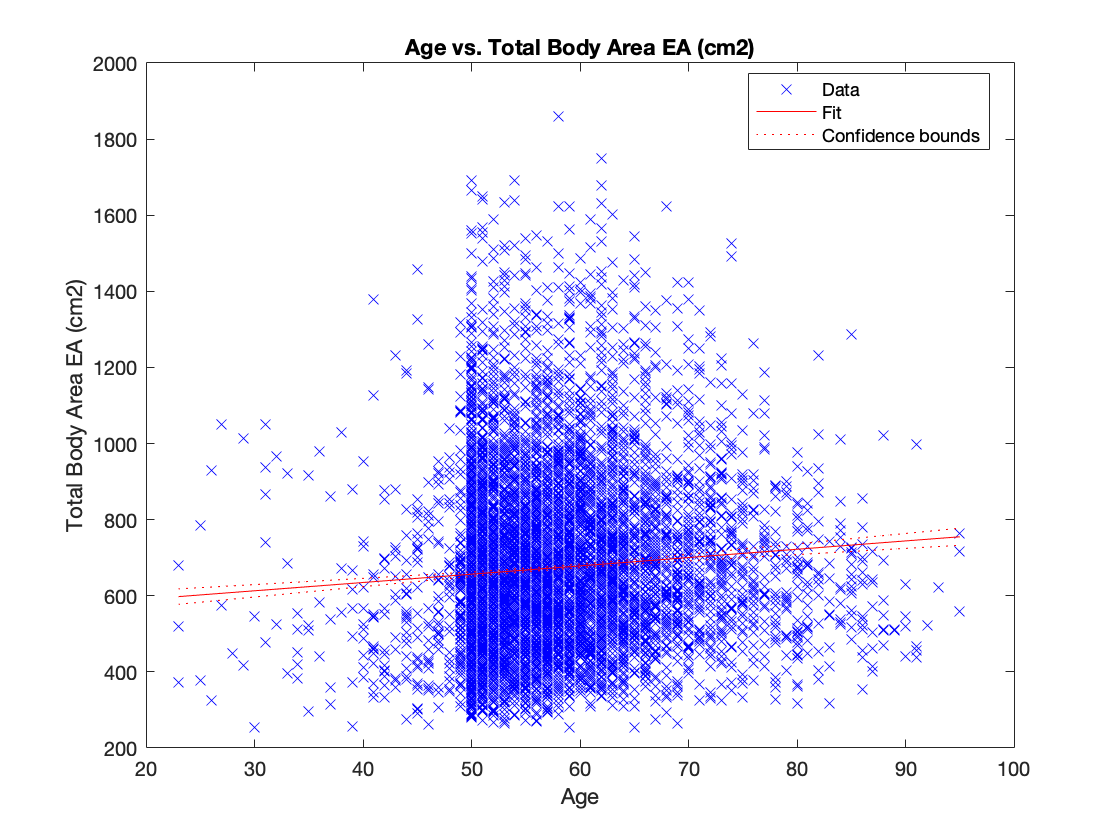

                   Estimate      SE       tStat       pValue   
                   ________    _______    ______    ___________
    (Intercept)     547.57      17.034    32.145    8.0291e-215
    x1              2.1837     0.29571    7.3846     1.6634e-13


The variable Total Body Area EA (cm2) is linearly related to age with p-value of 0.000000.

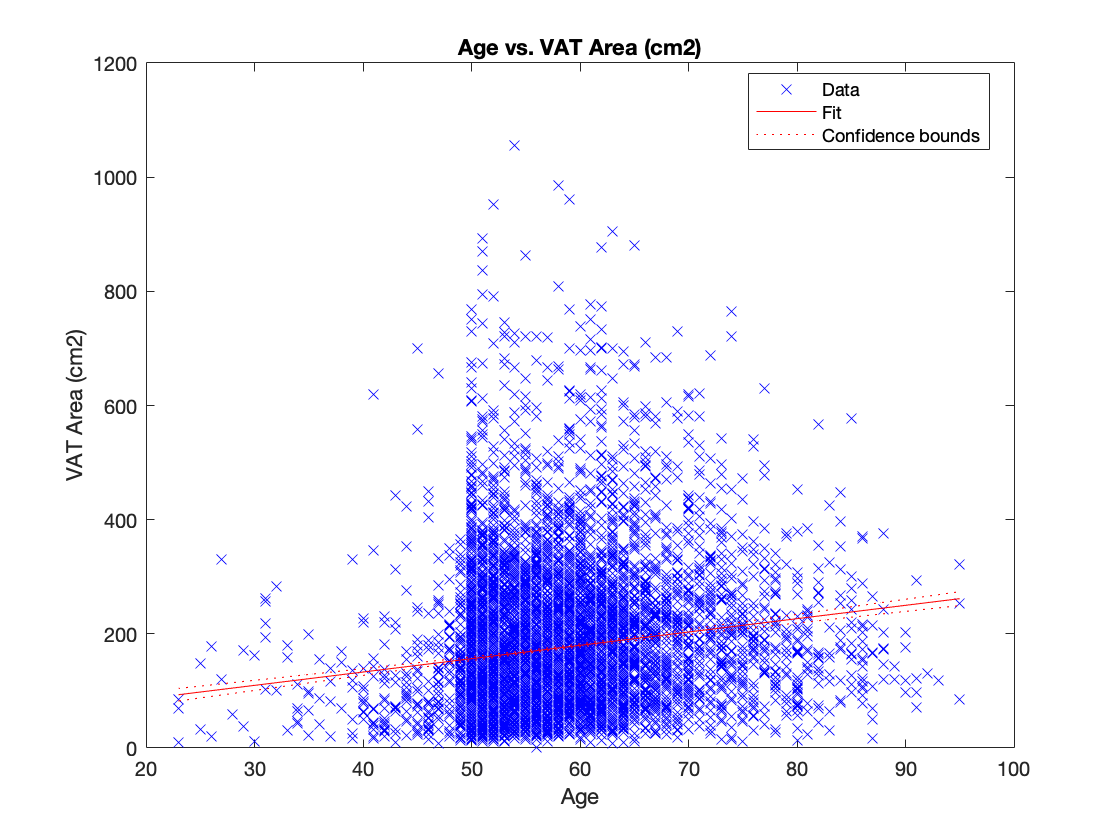

                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________
    (Intercept)     39.607      9.2359    4.2884     1.818e-05
    x1               2.337     0.16033    14.576    1.3706e-47


The variable VAT Area (cm2) is linearly related to age with p-value of 0.000000.

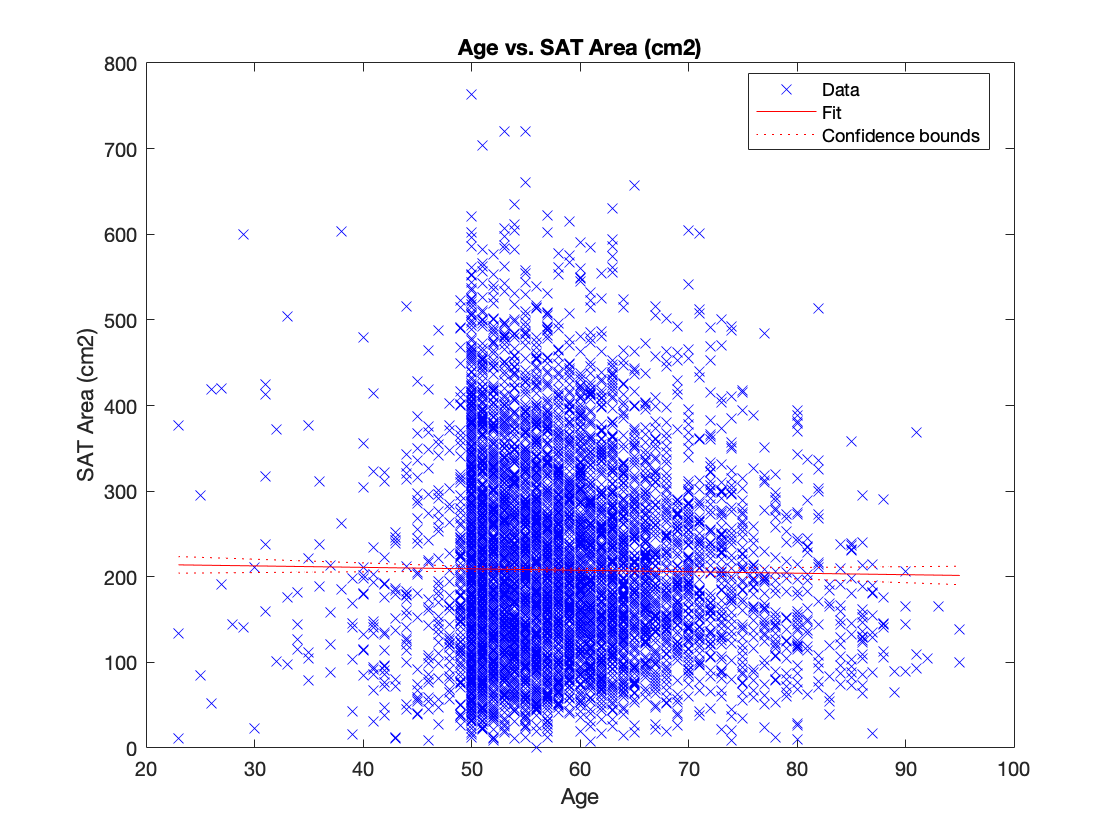

                   Estimate      SE      tStat       pValue   
                   ________    ______    ______    ___________
    (Intercept)      217.82    8.1513    26.722    1.6786e-151
    x1             -0.17122    0.1415     -1.21        0.22631


The variable SAT Area (cm2) is NOT linearly related to age.

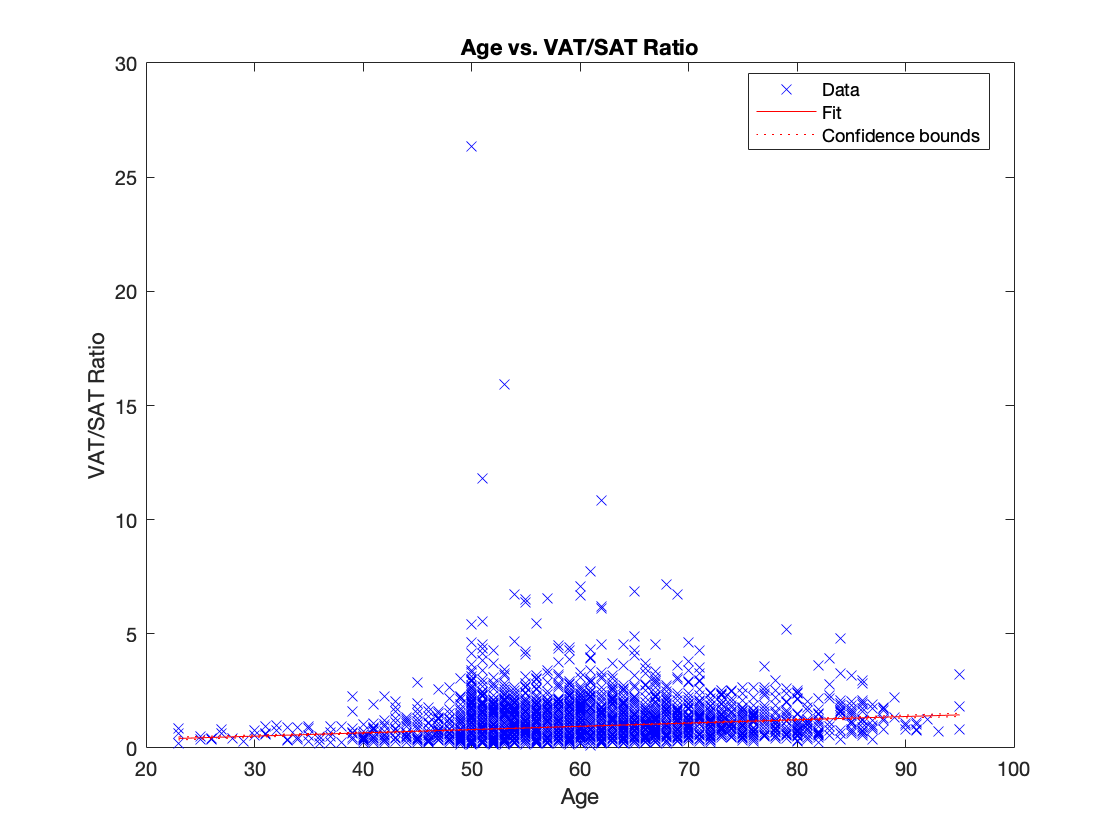

                   Estimate        SE        tStat       pValue  
                   ________    __________    ______    __________
    (Intercept)    0.089223      0.054361    1.6413       0.10077
    x1             0.014333    0.00094368    15.188    1.8164e-51


The variable VAT/SAT Ratio is linearly related to age with p-value of 0.000000.

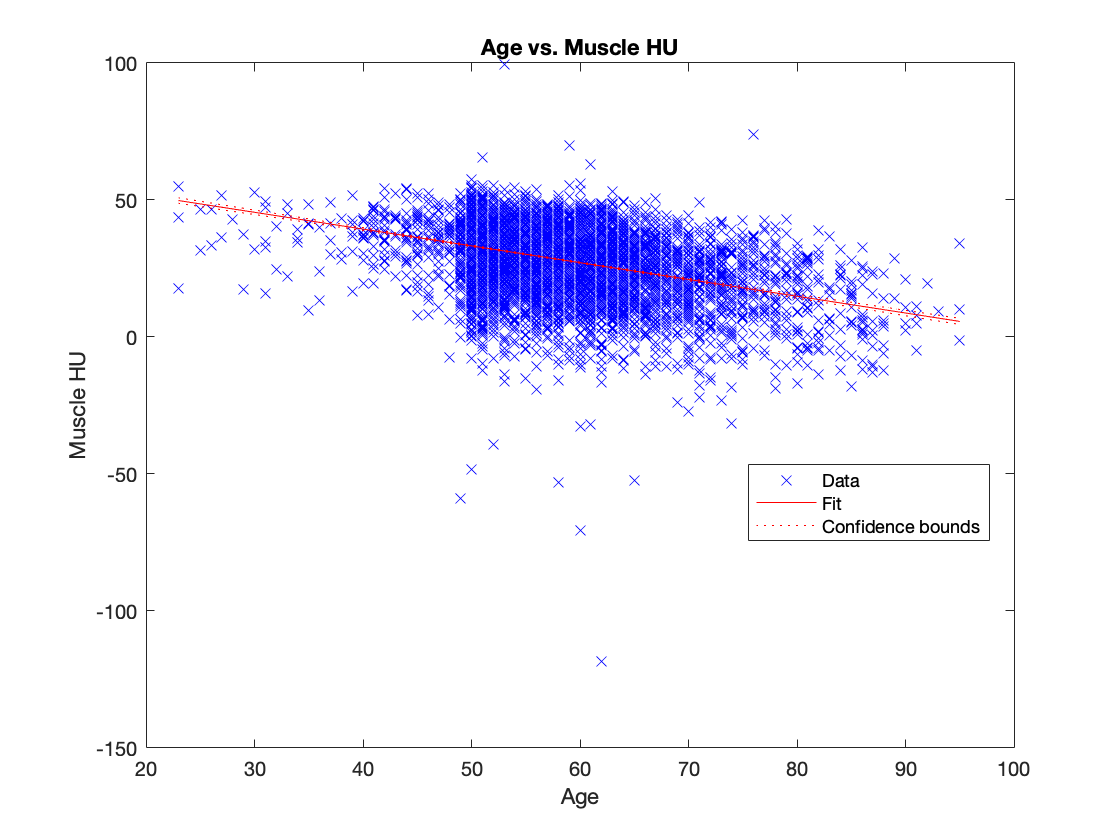

                   Estimate       SE        tStat     pValue
                   ________    ________    _______    ______
    (Intercept)     63.889      0.85422     74.792      0   
    x1             -0.6126     0.014823    -41.327      0   


The variable Muscle HU is linearly related to age with p-value of 0.000000.

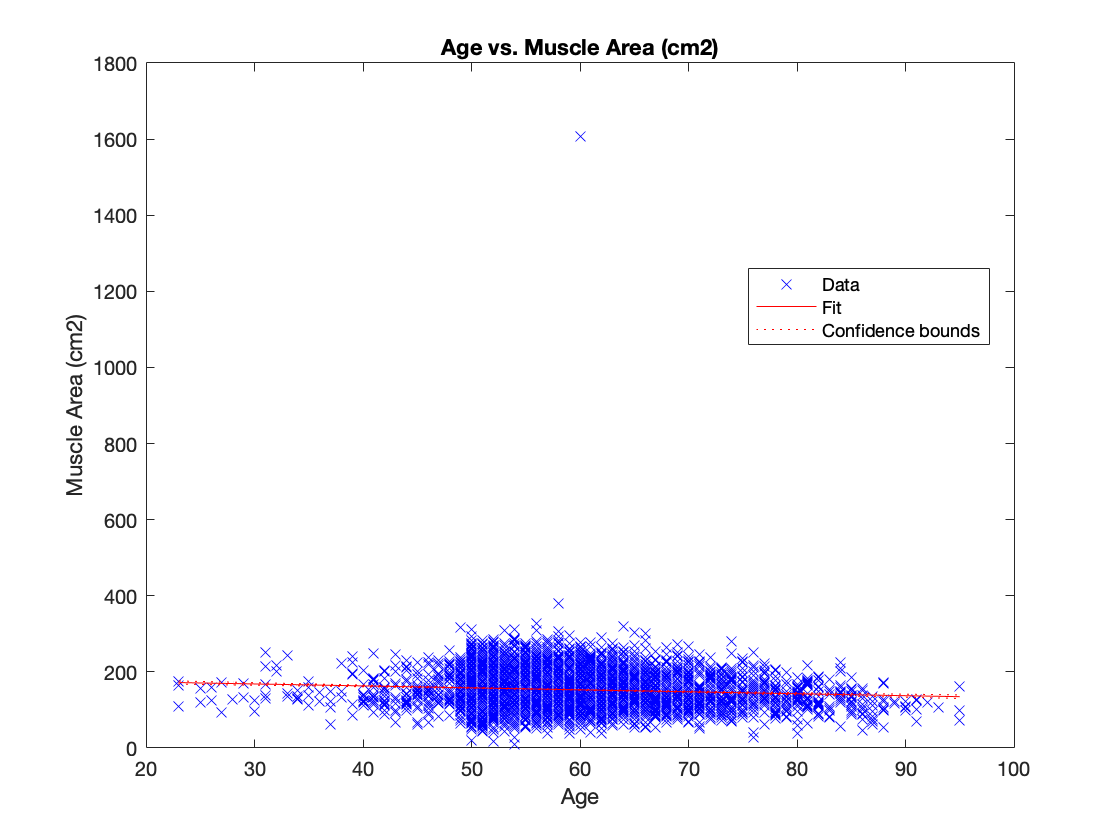

                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________
    (Intercept)      183.77      3.5151     52.279             0
    x1             -0.51502    0.060998    -8.4432    3.5555e-17


The variable Muscle Area (cm2) is linearly related to age with p-value of 0.000000.

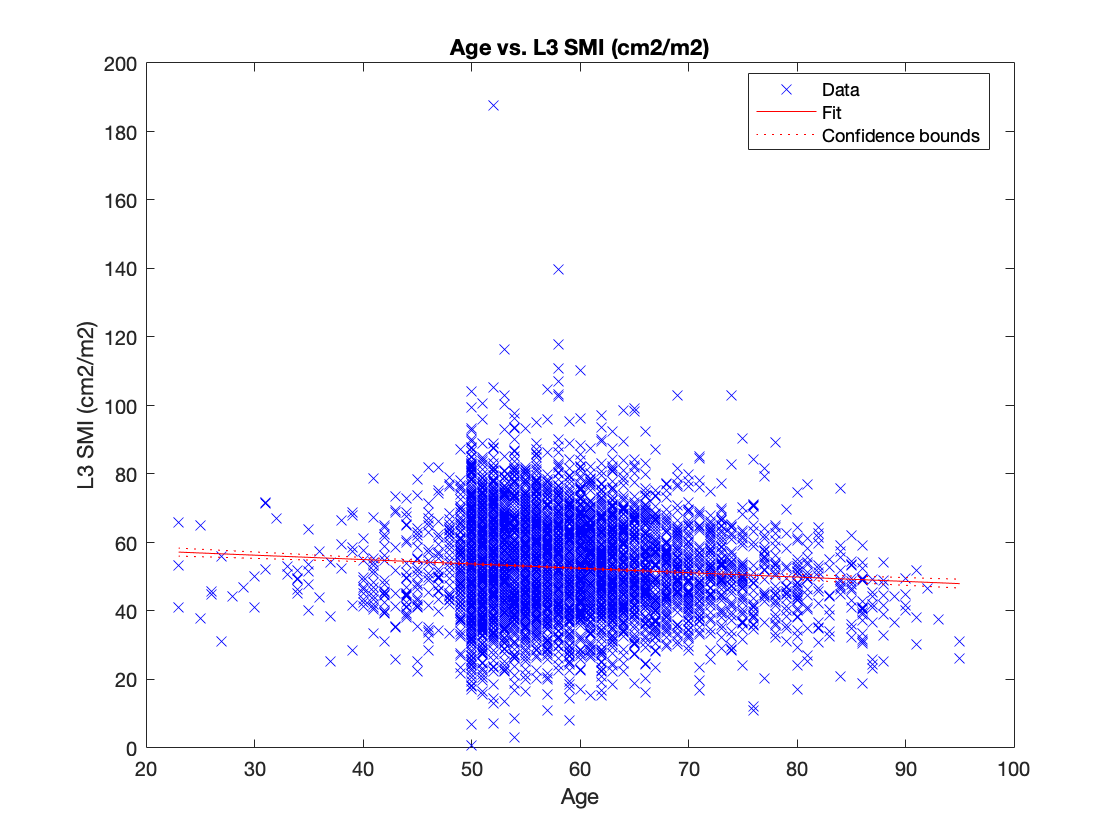

                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________
    (Intercept)      60.137     0.97686     61.562             0
    x1             -0.12782    0.016971    -7.5316    5.4932e-14


The variable L3 SMI (cm2/m2) is linearly related to age with p-value of 0.000000.

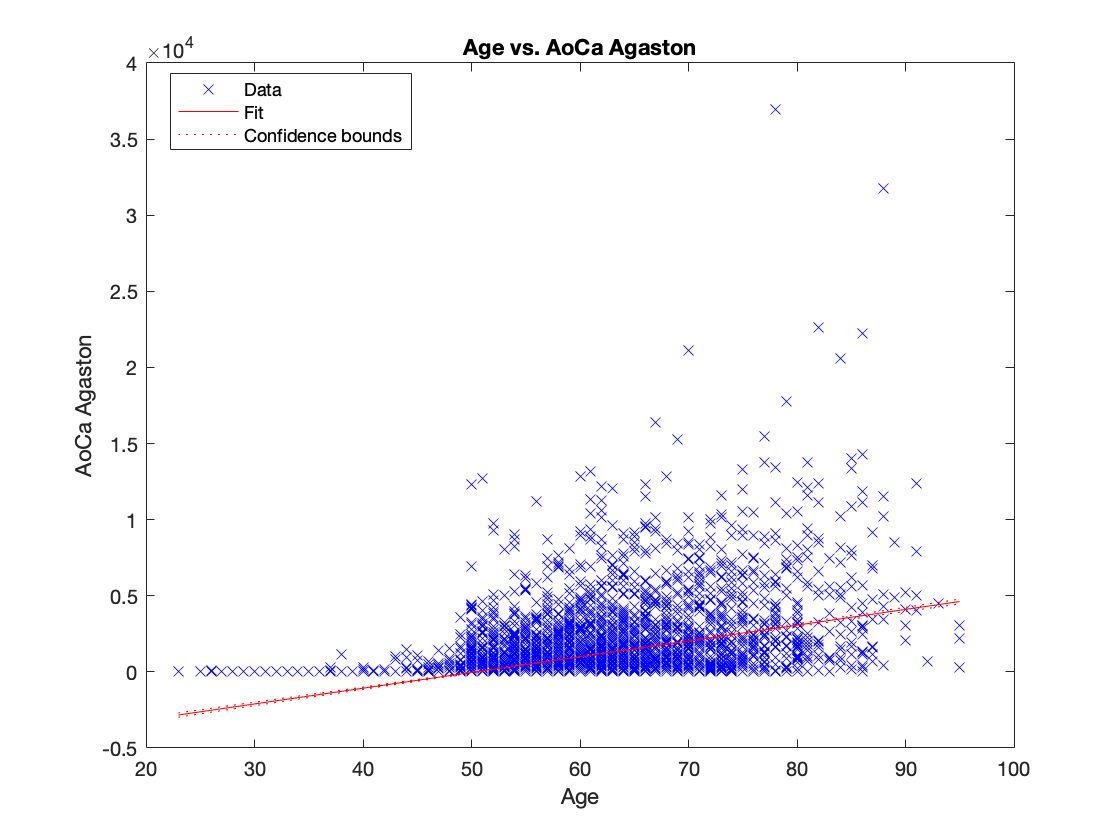

                   Estimate      SE       tStat     pValue
                   ________    ______    _______    ______
    (Intercept)    -5211.4     118.71    -43.899      0   
    x1              103.52       2.06     50.251      0   


The variable AoCa Agaston is linearly related to age with p-value of 0.000000.

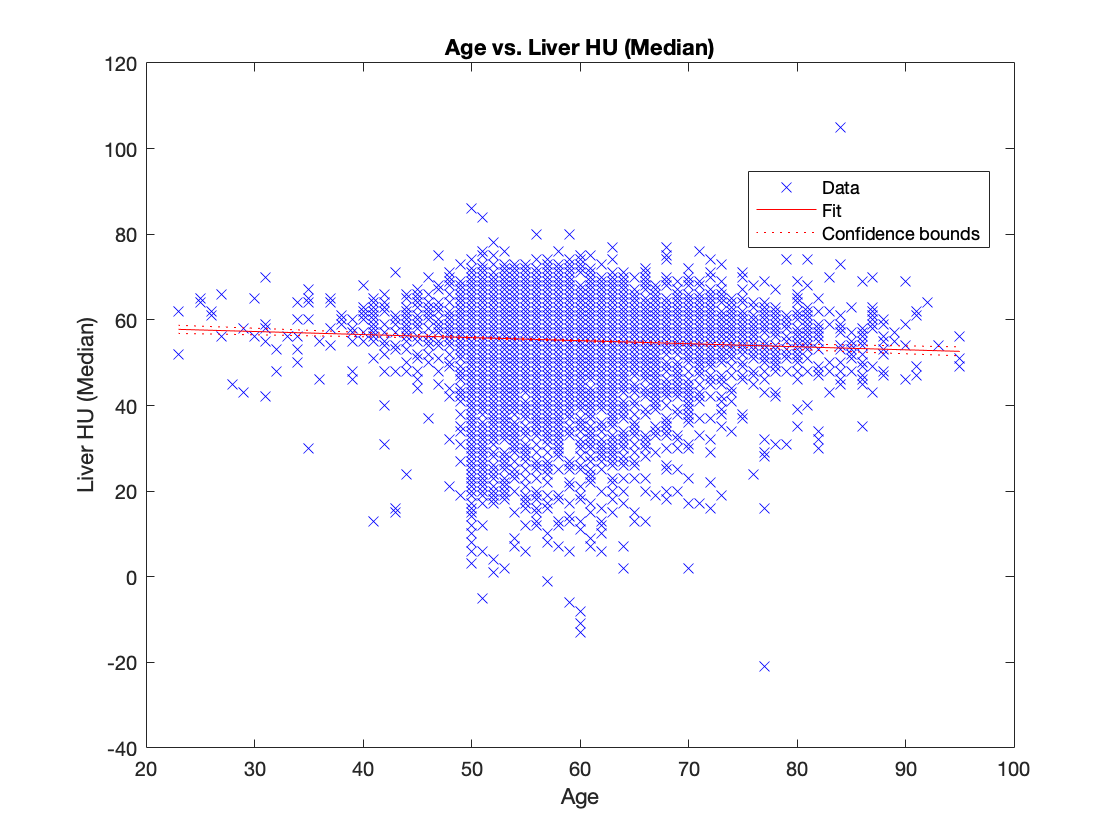

                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________
    (Intercept)       59.425     0.79824     74.445             0
    x1             -0.071315    0.013853    -5.1478    2.6903e-07


The variable Liver HU (Median) is linearly related to age with p-value of 0.000000.

for i = 1:width(CT)
    all_linearfits{i} = fitlm(data_clean(:,5),CT(:,i));
    figure;
    plot(all_linearfits{i})
    title("Age vs. "+CT_desc(i))
    ylabel(CT_desc(i))
    xlabel("Age")
    disp(all_linearfits{i}.Coefficients)
end

corrcoef([data_clean(:,5),CT],'Rows','pairwise');
disp(ans(1,:))

    1.0000   -0.3991    0.0879    0.0772    0.1511   -0.0127    0.1573   -0.3958   -0.0877   -0.0788    0.4637   -0.0537
